% LAB 2
clear
load TRC_display.mat

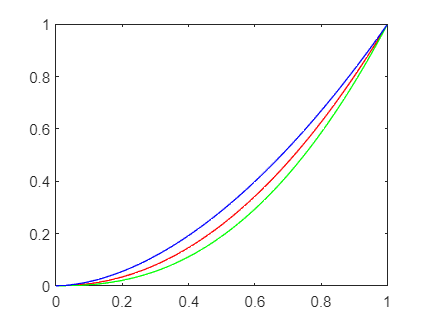

% 1.1
x = 0:0.01:1;
plot(x,TRCr,"Color","red")
hold on
plot(x, TRCg, "Color","green")
plot(x, TRCb, "Color","blue")

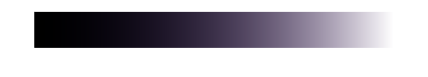

% 1.2
load Ramp_display.mat
load Ramp_linear.mat

Ramp_display(:,:,1);

LinearIm = linearize(TRCr, TRCg, TRCb, Ramp_display);

imshow(Ramp_display)

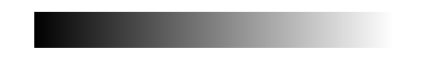

imshow(Ramp_linear)

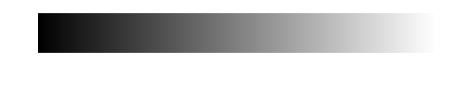

imshow(LinearIm)

function linearizedIm = linearize(r, g, b, im)
    x = 0:0.01:1;
    linearizedIm(:,:,1) = interp1(r, x, im(:,:,1), 'pchip');
    linearizedIm(:,:,2) = interp1(g, x, im(:,:,2), 'pchip');
    linearizedIm(:,:,3) = interp1(b, x, im(:,:,3), 'pchip');
end